%% Model Fitness Function from MATPOWER Data
close all
clear all
clc

# Modeling of Transmission System Objective Function

#### Select the Transmission System Test Case and Run:

mpc = loadcase("case300");
 
%Import MATPOWER Data

%Generators - Power Generation - Vector Interpolation
G_Pg = (linspace(sum(mpc.gen(:,10)), ...
                sum(mpc.gen(:,9)),  ...
                length(mpc.gen(:,1))));

%Generators - Coefficients
coefs = (mpc.gencost(:,5:7));


%Buses - Power Demand - Vector Interpolation
B_Pd = (linspace(sum(mpc.bus(:,13)), ...
                sum(mpc.bus(:,12)), ...
                length(G_Pg)));


[X,Y] = meshgrid(G_Pg,B_Pd);


z = [];
o = [];
name = {};

%Generators' Power Sum (Parabolic Equation)
% Each row is the power generation in between the generator's respective
% operational range
for i = 1:length(mpc.gen(:,1)) %1-Generators Number
%     y(i,:) = i*ones(1,37);
    if i==1
    o = [(coefs(i,1).*G_Pg.^2 + ...
          coefs(i,2).*G_Pg    + ...
          coefs(i,3))]; %#ok<*NBRAK2>
    z(i,:) = o;
    else 
    o = [(coefs(i,1).*G_Pg.^2 + ...
          coefs(i,2).*G_Pg    + ...
          coefs(i,3))];
    z(i,:) = o+z(i-1,:);
    end
    name(i) = {strcat('Gen ', num2str(i) ) };

end


[xData, yData, zData] = prepareSurfaceData( G_Pg, B_Pd, z );

% Set up fittype and options.
ft = fittype( 'poly55' );
warning('off','curvefit:fit:iterationLimitReached');
% Fit model to data.
[fitresult, gof, ft] = fit( [xData, yData], zData, ft, ...
                            'Normalize', 'on', ...
                            'Robust', 'Bisquare');

#### Scattered Data Plot:

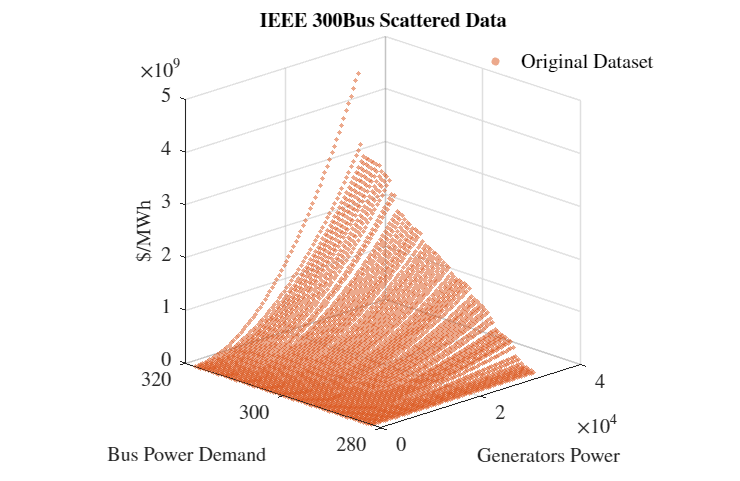

%% Plot fit with data.
hfig = figure(1);
hold on
%figure( 'Name', 'Polynomial Fit' );
scatter3( xData, yData, zData, ...
          10,...
          'filled', ...
          'marker', 'o', ...
          'MarkerEdgeColor','none', ...
          'MarkerFaceColor',"#D95319", ...
          'MarkerFaceAlpha', .5);

view([315.6 19.0])
pbaspect([1 1 1])

title('\bf IEEE 300Bus Scattered Data','Interpreter','latex')
legend('Original Dataset', ...
       'Location', 'Northeast', ...
       'Interpreter', 'latex');


% Label axes
xlabel( 'Generators Power','Interpreter', 'latex');
ylabel( 'Bus Power Demand','Interpreter', 'latex');
zlabel( '\$/MWh', 'Interpreter', 'latex' );

fname = 'MATPOWER Scattered Data';
picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.65; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),...
    'FontSize',15) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),...
    'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters',...
    'Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto',...
    'PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-painters','-fillpage')
print(hfig,fname,'-dpng','-vector','-r300')
grid on
hold off

#### Polynomial Model Plot:

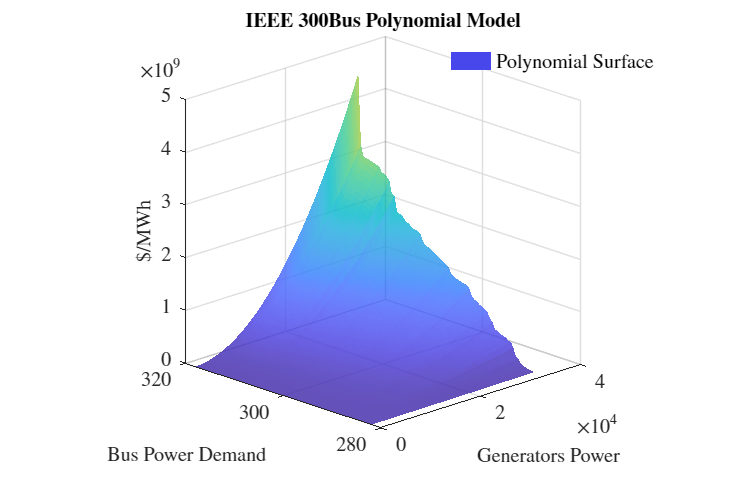

%----------------------------------------------------------------%
hfig = figure(2);
hold on
%figure( 'Name', 'Polynomial Fit' );

surf( G_Pg, B_Pd, z, ...
    'EdgeColor','none',...
    'LineStyle', '-',...
    'FaceAlpha',0.8)

view([315.6 19.0])
pbaspect([1 1 1])

title('\bf IEEE 300Bus Polynomial Model','Interpreter','latex')
legend('Polynomial Surface', ...
       'Location', 'Northeast', ...
       'Interpreter', 'latex');


% Label axes
xlabel( 'Generators Power','Interpreter', 'latex');
ylabel( 'Bus Power Demand','Interpreter', 'latex');
zlabel( '\$/MWh', 'Interpreter', 'latex' );

fname = 'MATPOWER Polynomial Function';
picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.65; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),...
    'FontSize',15) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),...
    'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters',...
    'Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto',...
    'PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-painters','-fillpage')
print(hfig,fname,'-dpng','-vector','-r300')
grid on
hold off

#### **Polynomial function generated:**

disp(fitresult)

     Linear model Poly55:
     fitresult(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2 + p30*x^3 
                    + p21*x^2*y + p12*x*y^2 + p03*y^3 + p40*x^4 + p31*x^3*y 
                    + p22*x^2*y^2 + p13*x*y^3 + p04*y^4 + p50*x^5 + p41*x^4*y 
                    + p32*x^3*y^2 + p23*x^2*y^3 + p14*x*y^4 + p05*y^5
       where x is normalized by mean 1.634e+04 and std 9572
       and where y is normalized by mean 300 and std 10.55
     Coefficients (with 95% confidence bounds):
       p00 =   3.805e+08  (3.787e+08, 3.822e+08)
       p10 =   4.312e+08  (4.278e+08, 4.345e+08)
       p01 =   1.852e+08  (1.818e+08, 1.885e+08)
       p20 =   1.218e+08  (1.193e+08, 1.244e+08)
       p11 =   2.145e+08  (2.124e+08, 2.166e+08)
       p02 =  -2.476e+07  (-2.735e+07, -2.218e+07)
       p30 =   3.662e+06  (-6.239e+04, 7.387e+06)
       p21 =   5.718e+07  (5.424e+07, 6.013e+07)
       p12 =  -2.045e+07  (-2.34e+07, -1.751e+07)
       p03 =   3.532e+07  (3.159e+07, 3.904e+07)
    